% Clear old vars
clear
% Connect to raspi
rpi = raspi()

rpi =   raspi with properties:

         DeviceAddress: '192.168.1.213'               
                  Port: 18734                         
             BoardName: 'Raspberry Pi 3 Model B+'     
         AvailableLEDs: {'led0'}                      
  AvailableDigitalPins: [4,5,6,12,13,14,15,16,17,18,19,20,21,22,23,24,25,26,27]
  AvailableSPIChannels: {'CE0','CE1'}                 
     AvailableI2CBuses: {'i2c-1'}                     
      AvailableWebcams: {'bcm2835-isp (platform:bcm2835-isp)','mmal service 16.1 (platform:bcm2835-v4l2)'}
           I2CBusSpeed: 100000                        

  Supported peripherals



% Note: use webcam function instead if using a USB camera
cam = cameraboard(rpi,'Resolution','1280x720')

cam =   cameraboard with properties:

                    Name: Camera Board   
              Resolution: '1280x720'      (View available resolutions)
                 Quality: 10              (1 to 100)
                Rotation: 0               (0, 90, 180 or 270)
          HorizontalFlip: 0              
            VerticalFlip: 0              
               FrameRate: 30              (2 to 90)
               Recording: 0              

   Picture settings
              Brightness: 50              (0 to 100)
                Contrast: 0               (-100 to 100)
              Saturation: 0               (-100 to 100)
               Sharpness: 0               (-100 to 100)

   Exposure and AWB
            ExposureMode: 'auto'          (

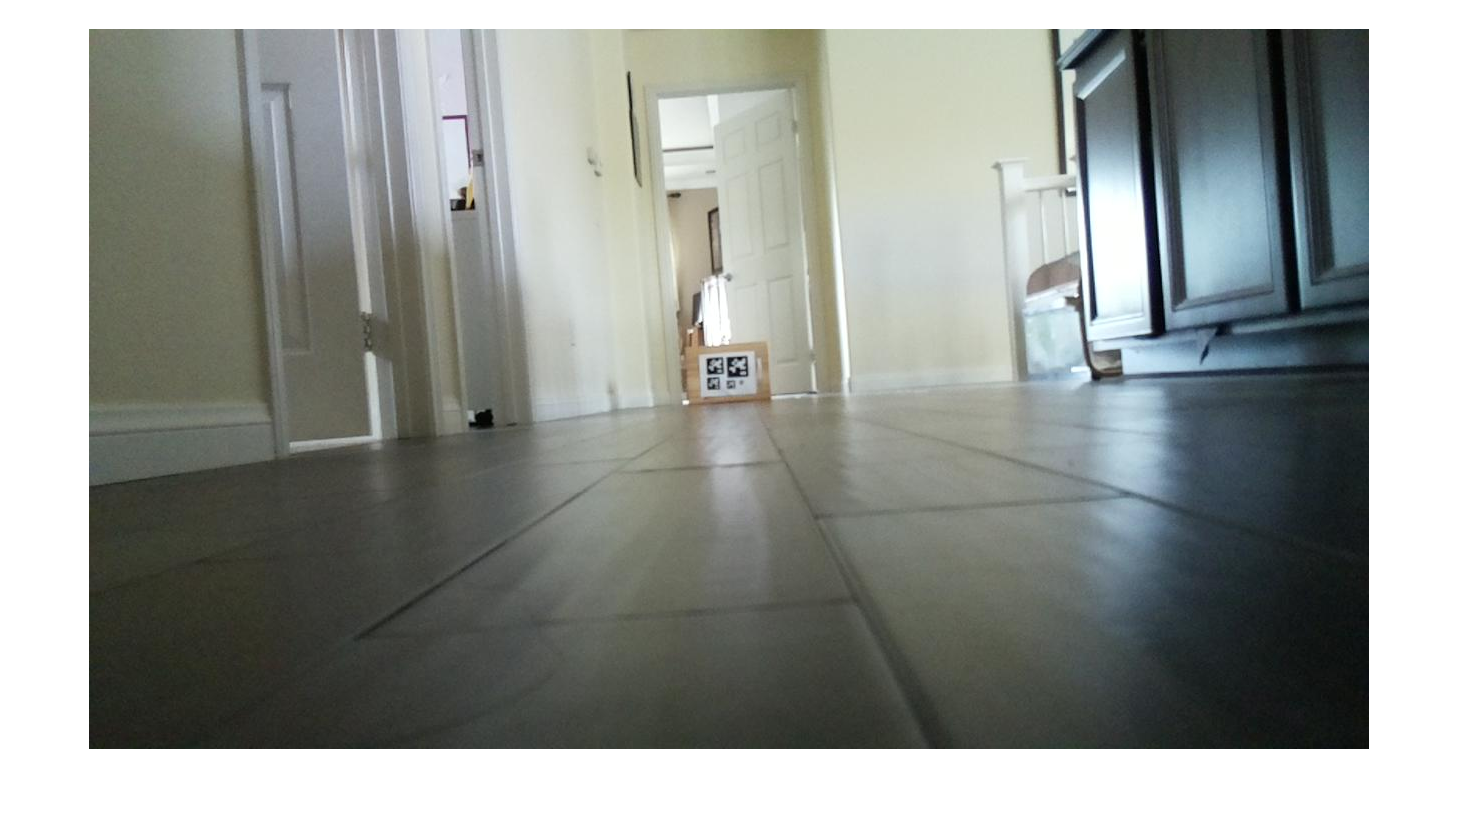

% Flush camera buffer
for v = 0:1:5
    % Take a photo using the camera
   I = snapshot(cam);
end

% Display image
figure, imshow(I)


centers =

  0×2 empty double matrix


ids =

  1×0 empty double row vector



%I = imread("ReadAprilTagsInImageExample_01.png");
[centers, ids] = detectAprilTags(I, true) % Change to false to suppress output

    function [centers, ids] = detectAprilTags(image, display)
    tagFamily = ["tag36h11"];
    
    [ids,loc,detectedFamily] = readAprilTag(image, tagFamily);
    
    centers = zeros(length(ids), 2);
    
    for idx = 1:length(ids)
        % Compute center of tag
        center = mean(loc(:,:,idx));

        % Add 2D center of tag to list
        centers(idx,:) = center;
        
        if display
            % Display the ID and tag family
            disp("Detected Tag ID, Family: " + ids(idx) + ", " ...
                + detectedFamily{idx})
            disp(loc)
            
            % Insert markers to indicate the locations
            markerRadius = 8;
            numCorners = size(loc,1);
            markerPosition = [loc(:,:,idx),repmat(markerRadius,numCorners,1)];
            image = insertShape(image,"FilledCircle",markerPosition,"Color","red","Opacity",1);
        end
    end
    
    if display
        imshow(image);
    end
end